VAJE 8

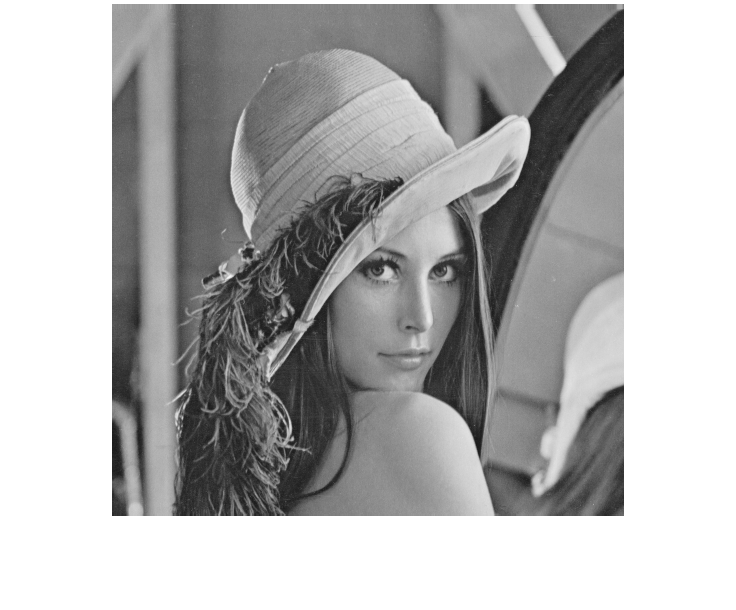

lenna = imread('Lenna.png');
gray = rgb2gray(lenna);
imshow(gray);

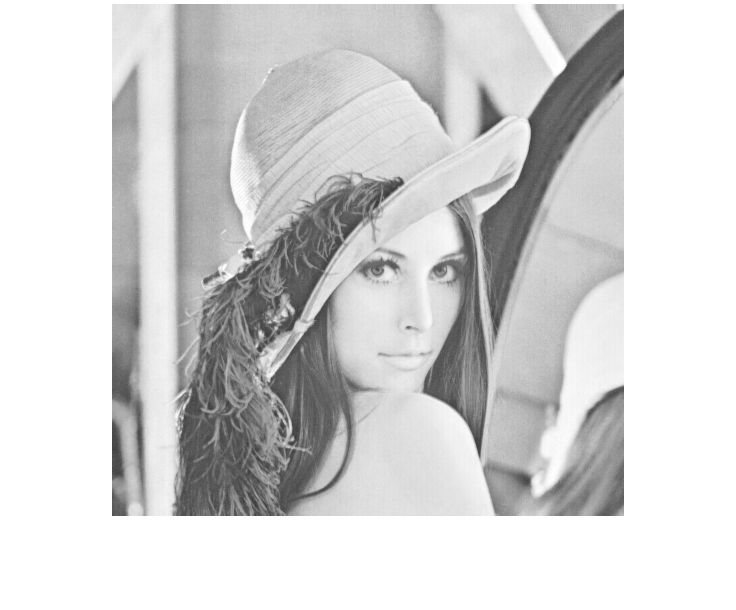

red = lenna(:,:,1);
imshow(red);

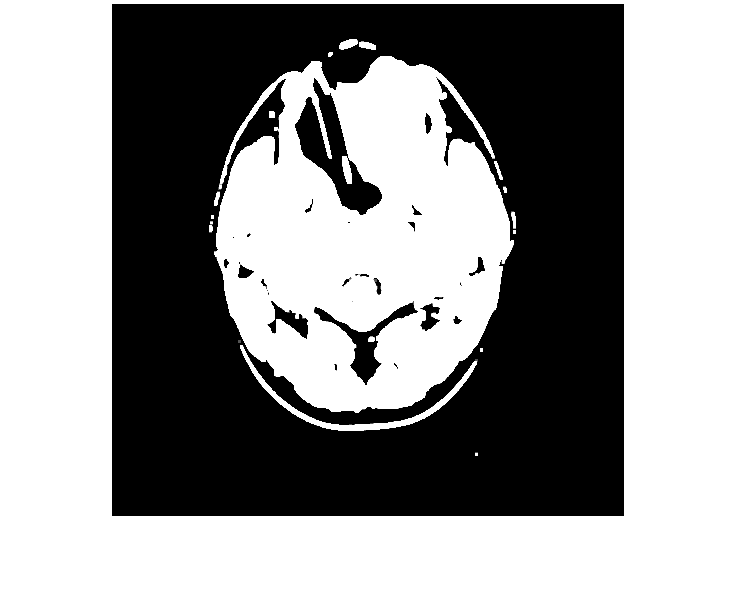


slice = imread('0001.png');
aslice = im2double(slice); % niso vec od 0-255 ampak 0-1
inv = 255 - slice;

kernel = ones(3)/9;
fslice = conv2(slice, kernel, 'same');
imshow(fslice);

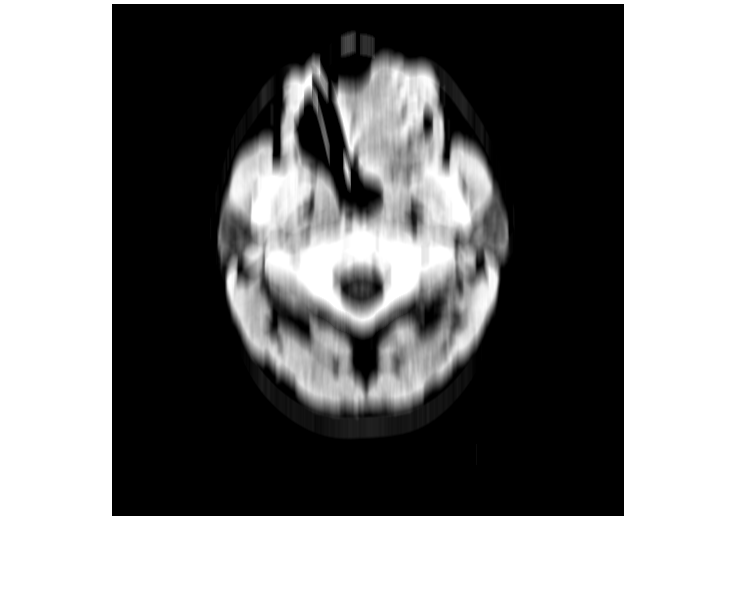

fslice = conv2(im2double(slice),kernel,'same');

kernel2 = ones(21);
kernel2 = kernel2/sum(kernel2);
fslice = conv2(im2double(slice),kernel2,'same');
imshow(fslice);   

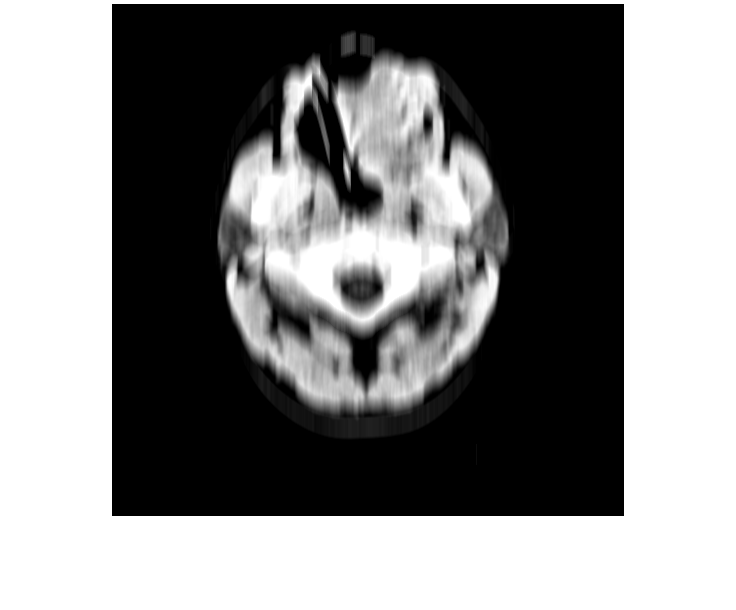


fslice = imfilter(slice, kernel2);
imshow(fslice);

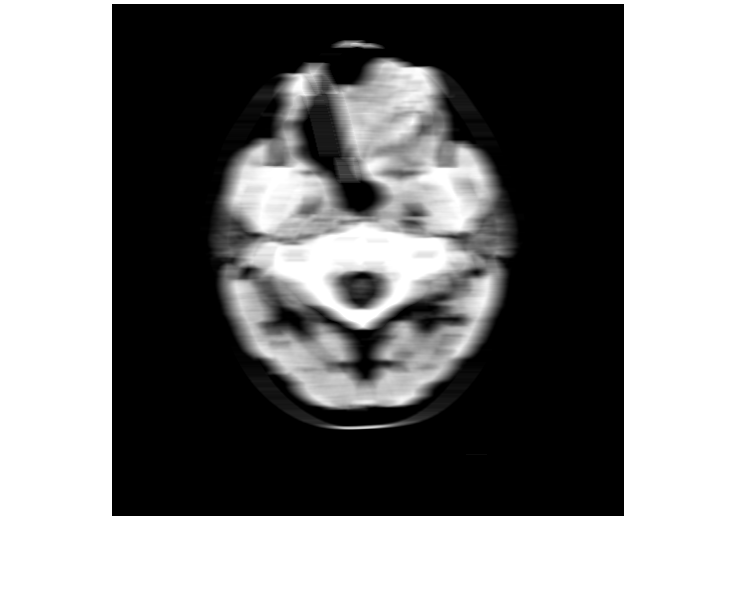


kernel3 = ones(1,21)/21; % motion blur levo desno
fslice = imfilter(slice,kernel3);
imshow(fslice)

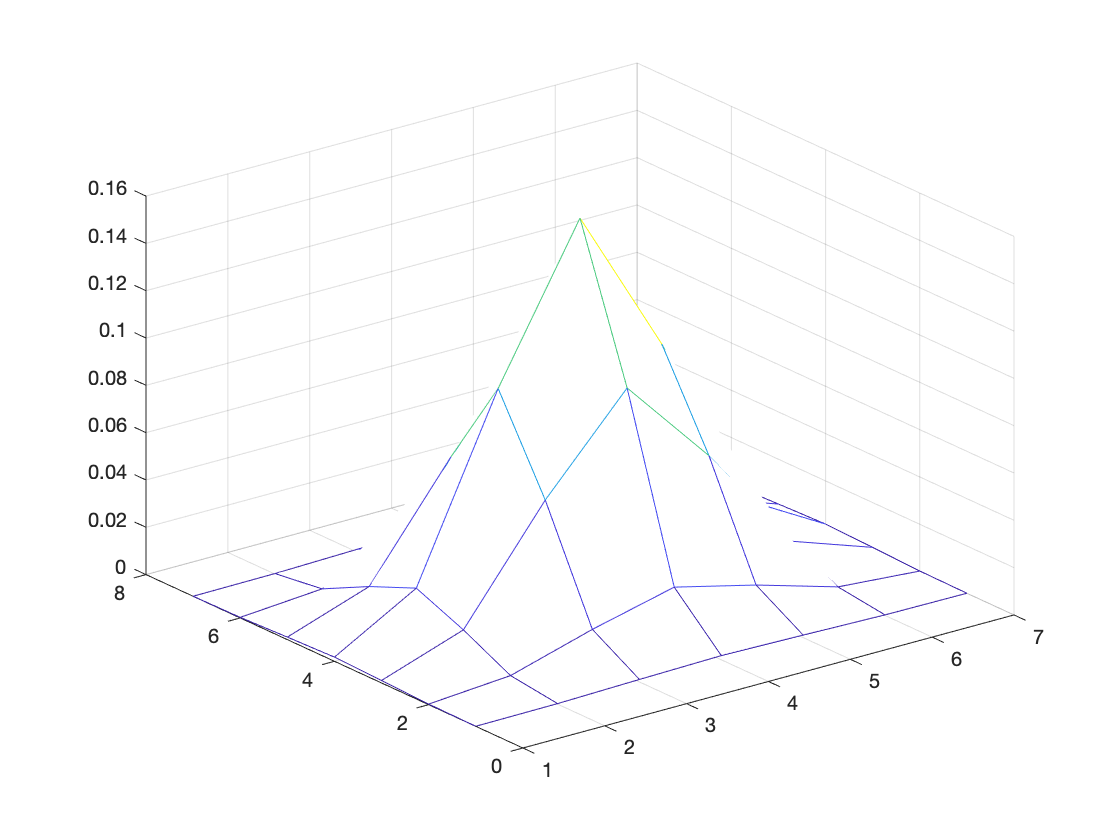

kernel = calcGauss(2.0);
kernel = fspecial('gaussian',[7 7],1.0);
mesh(kernel);


aslice = im2double(slice);

Error using slice (line 39)
Not enough input arguments.

fslice = conv2(aslice,kernel,'same');